# Practice of robot system toolbox with visulization

Peter Chang 2026/01/22

Example of using DH (standard) to build rigid body tree, also practice from "learning_jackobian" exercise

Spong's book Example 3.2 Cylindrical Robot base to arm no wrist definition

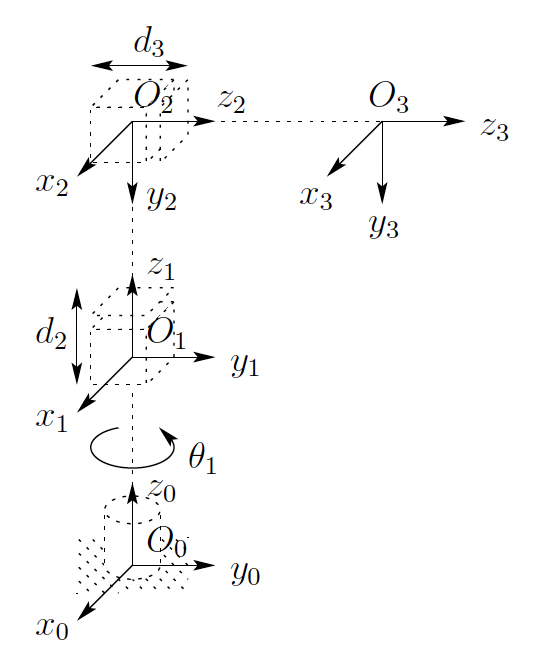

assume that a resonable table-top arm setup, the d-h table from the previous frame assignment shows: c means constant

this meant there are three rigid bodies: link1-revolute, link2-prismatic, link3-prismatic. R-P-P setup.

Asked ChatGPT to learn later assignement on future mass, moment of inertia, center of mass and "geometry" so on.

Now needs to focus on rigid body tree object usage and definition.

% comparison of MATLAB code and Craig's code
% using matlab robotics toolbox to create a rotbot (rigid body tree) object
% recall matlab document: https://www.mathworks.com/help/robotics/ug/build-manipulator-robot-using-kinematic-dh-parameters.html

close all;
clear;
clc



First learn to use rigid body for slow process and test Transform



% pre-assign 
th1 = 0;
d2 = .0; 
d3 = .0;

dhparams = [0 0 0.2 th1;0 -deg2rad(90) 0.2+d2 0;0 0 0.2+d3 0]

dhparams =          0         0    0.2000         0
         0   -1.5708    0.2000         0
         0         0    0.2000         0



[nrow ncol] = size(dhparams)

nrow = 3

ncol = 4

% create robot tree object
cy_robot = rigidBodyTree;

% Using cell array for rigid body object, another for joint object.
bodies = cell(nrow,1);
joints = cell(nrow,1);

    bodies{1} = rigidBody(['body' num2str(1)]);
    bodies{2} = rigidBody(['body' num2str(2)]);
    bodies{3} = rigidBody(['body' num2str(3)]);

    joints{1} = rigidBodyJoint(['jnt' num2str(1)],"revolute");
    joints{2} = rigidBodyJoint(['jnt' num2str(2)],"prismatic");
    joints{3} = rigidBodyJoint(['jnt' num2str(3)],"prismatic");

% iterate through dhparams to put in the cell array
for i = 1:nrow
    setFixedTransform(joints{i}, dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};    % don't forget this part!!!
    if i == 1 % add first body to base
        addBody(cy_robot,bodies{i},"base")
    else
        addBody(cy_robot,bodies{i},bodies{i-1}.Name)
    end
end

showdetails(cy_robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2    prismatic            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   
--------------------




% figure(Name="Plannar model")
% show(robot)
fig = figure('Name',"Cylindrical Robot", 'NumberTitle','off', 'WindowStyle','normal')

fig =   Figure (1: Cylindrical Robot) with properties:

      Number: 1
        Name: 'Cylindrical Robot'
       Color: [0.9608 0.9608 0.9608]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


ax = axes('Parent',fig)

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


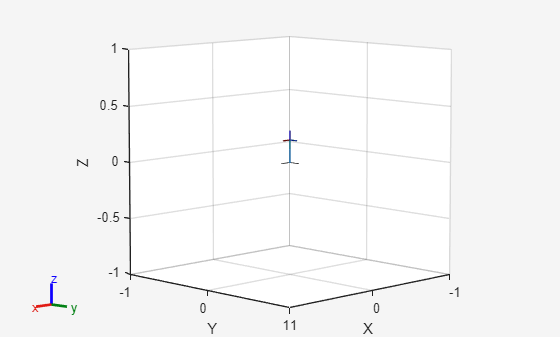

figure(fig)

show(cy_robot, 'Parent',ax,"Frames","on");
axis(ax,"equal")
grid(ax,"on")
rotate3d(fig,'on')

drawnow;

q = homeConfiguration(cy_robot);

for name = ["body1","body2","body3"]
    T = getTransform(cy_robot, q, name);
    p = tform2trvec(T);
    fprintf("%s origin = [%.4f %.4f %.4f]\n", name, p(1), p(2), p(3));
end

body1 origin = [0.0000 0.0000 0.2000]
body2 origin = [0.0000 0.0000 0.2000]
body3 origin = [0.0000 0.0000 0.2000]



rpy = tform2eul(T, "XYZ");   % roll-pitch-yaw (radians)



Right now this shows a little 